T = readtable('stock_prices.csv')

T = 2715×10 table
       Date        MSFT      AAPL      NFLX      WFC       ABT       GOOG      AMZN      JNJ        GS  
    __________    ______    ______    ______    ______    ______    ______    ______    ______    ______

    2010-01-04    24.168    6.6048      7.64    20.319    18.023     312.2     133.9    46.911    147.92
    2010-01-05    24.176    6.6162    7.3586    20.877    17.877    310.83    134.69    46.367    150.54
    2010-01-06    24.028     6.511    7.6171    20.906    17.976    302.99    132.25    46.744    148.93
    2010-01-07    23.778    6.4989    7.4857    21.665    18.125    295.94       130     46.41    151.84
    2010-01

symbol = T.Properties.VariableNames(2:end)

symbol = 1×9 cell array
    {'MSFT'}    {'AAPL'}    {'NFLX'}    {'WFC'}    {'ABT'}    {'GOOG'}    {'AMZN'}    {'JNJ'}    {'GS'}


dailyReturn = tick2ret(T{:,2:end})

dailyReturn =     0.0003    0.0017   -0.0368    0.0275   -0.0081   -0.0044    0.0059   -0.0116    0.0177
   -0.0061   -0.0159    0.0351    0.0014    0.0056   -0.0252   -0.0181    0.0081   -0.0107
   -0.0104   -0.0018   -0.0173    0.0363    0.0083   -0.0233   -0.0170   -0.0071    0.0196
    0.0069    0.0066    0.0172   -0.0093    0.0051    0.0133    0.0271    0.0034   -0.0189
   -0.0127   -0.0088   -0.0013   -0.0021    0.0051   -0.0015   -0.0240    0.0002   -0.0158
   -0.0066   -0.0114   -0.0162   -0.0250   -0.0029   -0.0177   -0.0227    0.0053   -0.0218
    0.0093    0.0141    0.0304    0.0178    0.0176   -0.0057    0.0138    0.0064    0.0074
    0.0201   -0.0058   -0.0550    0.0143    0.0011    0.0047   -0.0136    0.0020   -0.0032
   -0.0032   -0.0167   -0.0008   -0.0314    0.0025   -0.0167   -0.0016   -0.0083   -0.0197
    0.0078    0.0442    0.0049    0.0071    0.0128    0.0131    0.0037    0.0122    0.0100


p = Portfolio('AssetList', symbol, 'RiskFreeRate', 0.01/252)

p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: 3.9683e-05
        AssetMean: []
       AssetCovar: []
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 9
        AssetList: {'MSFT'  'AAPL'  'NFLX'  'WFC'  'ABT'  'GOOG'  'AMZN'  'JNJ'  'GS'}
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: []
       UpperBound: []
      LowerBudget: []
      UpperBudget: []
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


p = estimateAssetMoments(p, dailyReturn)

p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: 3.9683e-05
        AssetMean: [9×1 double]
       AssetCovar: [9×9 double]
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 9
        AssetList: {'MSFT'  'AAPL'  'NFLX'  'WFC'  'ABT'  'GOOG'  'AMZN'  'JNJ'  'GS'}
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: []
       UpperBound: []
      LowerBudget: []
      UpperBudget: []
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: []


p = setDefaultConstraints(p)

p =   Portfolio with properties:

          BuyCost: []
         SellCost: []
     RiskFreeRate: 3.9683e-05
        AssetMean: [9×1 double]
       AssetCovar: [9×9 double]
    TrackingError: []
     TrackingPort: []
         Turnover: []
      BuyTurnover: []
     SellTurnover: []
             Name: []
        NumAssets: 9
        AssetList: {'MSFT'  'AAPL'  'NFLX'  'WFC'  'ABT'  'GOOG'  'AMZN'  'JNJ'  'GS'}
         InitPort: []
      AInequality: []
      bInequality: []
        AEquality: []
        bEquality: []
       LowerBound: [9×1 double]
       UpperBound: []
      LowerBudget: 1
      UpperBudget: 1
      GroupMatrix: []
       LowerGroup: []
       UpperGroup: []
           GroupA: []
           GroupB: []
       LowerRatio: []
       UpperRatio: []
     MinNumAssets: []
     MaxNumAssets: []
        BoundType: [9×1 categorical]


w1 = estimateMaxSharpeRatio(p)

w1 =     0.0000
    0.3399
    0.1933
    0.0000
    0.2321
    0.0000
    0.2347
    0.0000
    0.0000


[risk1, ret1] = estimatePortMoments(p, w1)

risk1 = 0.0145

ret1 = 0.0013

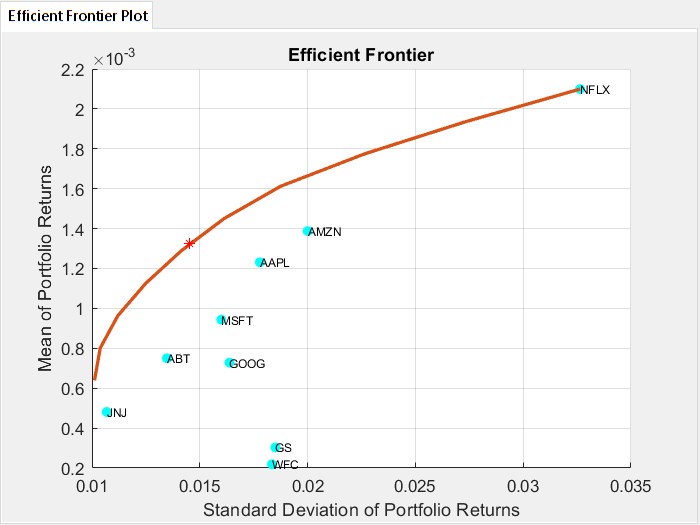

f = figure;
tabgp = uitabgroup(f);
tabl = uitab(tabgp, 'Title', 'Efficient Frontier Plot');
ax = axes('Parent', tabl);
[m, cov] = getAssetMoments(p);
scatter(ax,sqrt(diag(cov)), m, 'oc', 'filled');
xlabel('Risk')
ylabel('Expected Return')
text(sqrt(diag(cov)),m,symbol,'Fontsize',7);
hold on
plotFrontier(p)
hold on
plot(risk1, ret1, '*r')
hold off